# Ejemplo N8: Solución Matricial de un Portico Resistente a Momento [PRM]. desarrollado automatico con base en el método matricial de Rigidez. a traves de ensamblaje Directo.

- **Author:**              [ Msc. Ing. Carlos Andrés Celi Sánchez. ](https://www.researchgate.net/profile/Carlos_Celi)

- **Course:    **          Análisis Matricial de Estructuras.

- **University:**         [Pontificia Universidad Católica del Ecuador](https://www.puce.edu.ec/)

- **Year:    **               2019 B.

A continuación se presenta las operaciones automaticas del ejercicio en cuestión. El desarrollo matematico y deductivo se realizó en las clases respectivas: La solución se realiza con base en el planteamiento matricial del método de rigidez; Además, los calculos se automatizaron con base en un proceso de esamblaje directo en función de vectores de colocación.

Cleaning        

clc
clear
close all

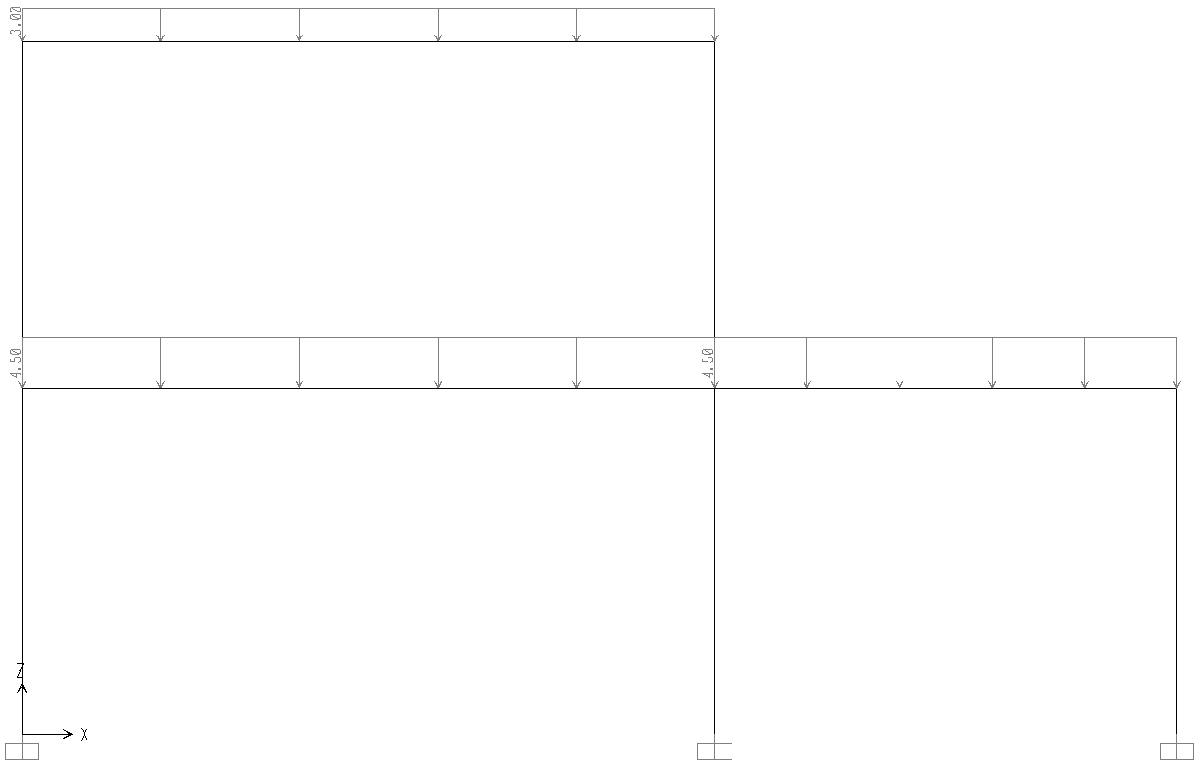

Datos:

L1=6;
L2=4;
H=3;
Ac=0.3*0.3;
Av=0.2*0.4;
Ic=0.3^4/12;
Iv=0.2*0.4^3/12;
E=2100000;
Le=[L1;L1;L2;H;H;H;H;H];
EI=[E*Iv;E*Iv;E*Iv;E*Ic;E*Ic;E*Ic;E*Ic;E*Ic];
EA=[Av*E;Av*E;Av*E;Ac*E;Ac*E;Ac*E;Ac*E;Ac*E];
nglt=24;                        % grados de libertad incluidas restricciones.
gdl=15;                         % grados de libertad.
primera_reaccion = 16;          % numeración de la primera reacción.

# 1.0. Calculo de la Matriz de Rigidez de Elemento. [Coordenadas de Elemento (Locales)].

- De acuerdo con la deducción realizada en clases. y respetando los signos de dicha deducción. La matriz de rigidez de elemento (tipo portico resistente a momento [PRM], con tres deformaciones por nudo) es la siguiente:


$$K_{\textrm{elemento}} =\left\lbrack \begin{array}{cccccc}
\frac{\mathrm{AE}}{L} & 0 & 0 & -\frac{\mathrm{AE}}{L} & 0 & 0\\
0 & \frac{12\mathrm{EI}}{L^3 } & \frac{6\mathrm{EI}}{L^2 } & 0 & -\frac{12\mathrm{EI}}{L^3 } & \frac{6\mathrm{EI}}{L^2 }\\
0 & \frac{6\mathrm{EI}}{L^2 } & \frac{4\mathrm{EI}}{L} & 0 & -\frac{6\mathrm{EI}}{L^2 } & \frac{2\mathrm{EI}}{L}\\
-\frac{\mathrm{AE}}{L} & 0 & 0 & \frac{\mathrm{AE}}{L} & 0 & 0\\
0 & -\frac{12\mathrm{EI}}{L^3 } & -\frac{6\mathrm{EI}}{L^2 } & 0 & \frac{12\mathrm{EI}}{L^3 } & -\frac{6\mathrm{EI}}{L^2 }\\
0 & \frac{6\mathrm{EI}}{L^2 } & \frac{2\mathrm{EI}}{L} & 0 & -\frac{6\mathrm{EI}}{L^2 } & \frac{4\mathrm{EI}}{L}
\end{array}\right\rbrack$$


## 1.1. Ordenamiento de matrices de rigidez de elementos (coordenadas locales).

- Puesto que se desea confeccionar la matriz de rigidez de la estructura en coordenadas globales. Es importante pero no absulutamente necesario confeccionar una matriz auxiliar en la que podamos colocar de forma ordenada las distintas matrices de rigidez de cada elemento (en coordenadas locales) una bajo la otra:


$$K_{\mathrm{aux}} =\left\lbrack \begin{array}{c}
{\left\lbrack \begin{array}{c}
K
\end{array}\right\rbrack }_{\mathrm{elemento},1} \\
{\left\lbrack \begin{array}{c}
K
\end{array}\right\rbrack }_{\mathrm{elemento},\;2} \\
\ldotp \\
\ldotp \\
{\left\lbrack \begin{array}{c}
K
\end{array}\right\rbrack }_{\mathrm{elemento},\;n} 
\end{array}\right\rbrack$$


format short
j=1;
for i=1:length(Le)
    k_ele_local(j:j+5,:)=K_elem_MP_6x6(EA(i),EI(i),Le(i));
    j=j+6;
end
table(k_ele_local)

ans = 48×1 table
    k_ele_local 
    ____________

    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]


# 2.0 Matriz de Transformación o Colocación & Matriz de Rigidez de Elemento. [Coordenadas Globales]. 

- De acuerdo con la deducción realizada en clases. y respetando los signos de dicha deducción. La matriz de Transformación de elemento (tipo portico resistente a momento [PRM], con tres deformaciones por nudo) es la siguiente:


$$T_{\textrm{elemento}} =\left\lbrack \begin{array}{cccccc}
\mathrm{cos}\left(\alpha \right) & -\mathrm{sin}\left(\alpha \right) & 0 & 0 & 0 & 0\\
\mathrm{sin}\left(\alpha \right) & \mathrm{cos}\left(\alpha \right) & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & \mathrm{cos}\left(\alpha \right) & -\mathrm{sin}\left(\alpha \right) & 0\\
0 & 0 & 0 & \mathrm{sin}\left(\alpha \right) & \mathrm{cos}\left(\alpha \right) & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack$$


## 2.1. Ordenamiento de matrices de transformación de elementos. (coordenadas locales a coordenadas globales).

- Puesto que se desea transformar la matriz de rigidez de cada elemento de coordenadas locales a coordenadas globales. Es importante pero no absulutamente necesario confeccionar una matriz auxiliar en la que podamos colocar de forma ordenada las distintas matrices de transformación de cada elemento una bajo la otra:


$$T_{\textrm{aux}} =\left\lbrack \begin{array}{c}
{\left\lbrack \begin{array}{c}
T
\end{array}\right\rbrack }_{\textrm{elemento},1} \\
{\left\lbrack \begin{array}{c}
T
\end{array}\right\rbrack }_{\textrm{elemento},\;2} \\
\ldotp \\
\ldotp \\
{\left\lbrack \begin{array}{c}
T
\end{array}\right\rbrack }_{\textrm{elemento},\;n} 
\end{array}\right\rbrack$$


alfas=[0;0;0;90;90;90;90;90];
j=1;
for i=1:length(Le)
    Ta(j:j+5,:) = T_elem_MP_6x6(alfas(i));
    j=j+6;
end
table(Ta)

ans = 48×1 table
         Ta     
    ____________

    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]


## 2.2. Matriz de Rigidez de Elemento en coordenadas Globales. ${\left\lbrack \begin{array}{c}
k_e 
\end{array}\right\rbrack }_G =\left\lbrack \begin{array}{c}
T
\end{array}\right\rbrack \times {\left\lbrack \begin{array}{c}
k_e 
\end{array}\right\rbrack }_L \times {\left\lbrack \begin{array}{c}
T
\end{array}\right\rbrack }^t$.

- Recuerde que la matriz de colocación "T" permite la pasar de un sistema coordenado a otro. en el presente caso de un sistema de coordenadas locales a un sistema de coordenadas globales.


$${\left\lbrace \Delta_e \right\rbrace }_L ={\left\lbrack \begin{array}{c}
T_e 
\end{array}\right\rbrack }^t \times {\left\lbrace \Delta_e \right\rbrace }_G$$



$${\left\lbrace F_e \right\rbrace }_G =\left\lbrack \begin{array}{c}
T_e 
\end{array}\right\rbrack \times {\left\lbrace F_e \right\rbrace }_L$$



$${\left\lbrace F_e \right\rbrace }_G =\left\lbrack \begin{array}{c}
T_e 
\end{array}\right\rbrack \times {\left\lbrack \begin{array}{c}
k_e 
\end{array}\right\rbrack }_L \times {\left\lbrack \begin{array}{c}
T_e 
\end{array}\right\rbrack }^t \times {\left\lbrace F_e \right\rbrace }_L$$



$${\left\lbrack \begin{array}{c}
k_e 
\end{array}\right\rbrack }_G =\left\lbrack \begin{array}{c}
T_e 
\end{array}\right\rbrack \times {\left\lbrack \begin{array}{c}
k_e 
\end{array}\right\rbrack }_L \times {\left\lbrack \begin{array}{c}
T_e 
\end{array}\right\rbrack }^t$$


Donde:

${\left\lbrace \Delta_e \right\rbrace }_L$ =         Vector de desplazamientos de elemento. correspondiente a los grados de libertad escogidos del elemento. [en coordenadas locales].

$\left\lbrack \begin{array}{c}
T_e 
\end{array}\right\rbrack$    =          Matriz de trasnformación de coordenadas de elemento.

${\left\lbrace F_e \right\rbrace }_G$  =         Vector de fuerzas de elemento. correspondiente a los grados de libertad escogidos de la estructura. [en coordenadas globales].

${\left\lbrace F_e \right\rbrace }_L$  =         Vector de fuerzas de elemento. correspondiente a los grados de libertad escogidos del elemento. [en coordenadas locales].

${\left\lbrack \begin{array}{c}
k_e 
\end{array}\right\rbrack }_L$   =          Matriz de rigidez de elemento. correspondiente a los grados de libertad escogidos del elemento. [en coordenadas locales].

${\left\lbrack \begin{array}{c}
k_e 
\end{array}\right\rbrack }_G$   =          Matriz de rigidez de elemento. correspondiente a los grados de libertad escogidos de la estructura. [en coordenadas globales].

## 2.2.1. Generación de Matriz de rigidez de elemento en coordenadas globales.

- Es importante pero no absulutamente necesario confeccionar una matriz auxiliar en la que podamos colocar de forma ordenada las distintas matrices de rigidez en coordenadas globales de cada elemento una bajo la otra:


$${\left\lbrack \begin{array}{c}
K_{\mathrm{elemento}} 
\end{array}\right\rbrack }_G =\left\lbrack \begin{array}{c}
{\left\lbrack \begin{array}{c}
K_{\mathrm{elemento},1} 
\end{array}\right\rbrack }_G \\
{\left\lbrack \begin{array}{c}
K_{\mathrm{elemento},1} 
\end{array}\right\rbrack }_G \\
\ldotp \\
\ldotp \\
{\left\lbrack \begin{array}{c}
K_{\mathrm{elemento},n} 
\end{array}\right\rbrack }_G 
\end{array}\right\rbrack$$


Tat=Ta';
z=1;
for i=1:length(Le)
    kta(z:z+5,:)=Ta(z:z+5,:)*k_ele_local(z:z+5,:)*Tat(:,z:z+5);
    z=z+6;
end
table(kta)

ans = 48×1 table
        kta     
    ____________

    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]
    [1x6 double]


# 3.0. Calculo de la Matriz de Rigidez de la Estructura incluido restricciones de apoyo. [Coordenadas Globales & Coordenadas Locales].

## 3.1. Vectores de Colocación. Referidos a los GDL de cada nudo de cada elemento. [nudo "i" y nudo "j"].

- Recuerde que, los vectores de colocación, numeran los GDL desde el nudo "i" al "j" siguiendo el orden para la deducción realizada en clases. Ademas recuerde que los nudos "i" & "j" dependen de la posición del observador.


$${\left\lbrace \mathrm{Lee}\right\rbrace }_{\mathrm{ELEMENTO},N\ldotp } =\left\lbrace \left\lbrack \begin{array}{c}
{\mathrm{GDL}}_{i,X} \\
{\mathrm{GDL}}_{i,Y} \\
{\mathrm{GDL}}_{j,X} \\
{\mathrm{GDL}}_{j,Y} 
\end{array}\right\rbrack \right\rbrace$$


Donde:

$\left\lbrace \textrm{Lee}\right\rbrace$      =   Vector de colocación del elemento "n".

${\textrm{GDL}}_{i,X}$     =   Numero de GDL, en dirección horizontal "X", correspondiente al nudo " i " del elemento.    

${\textrm{GDL}}_{i,Y}$     =   Numero de GDL, en dirección vertical "Y", correspondiente al nudo " i " del elemento.

${\textrm{GDL}}_{j,X}$     =   Numero de GDL, en dirección horizontal "X", correspondiente al nudo " j " del elemento.

${\textrm{GDL}}_{j,Y}$     =   Numero de GDL, en dirección vertical "Y", correspondiente al nudo " j " del elemento.

Lee(1,:)=[1 2 3 4 5 6];                      % Vector de ensamble elemento 1 %
Lee(2,:)=[7 8 9 10 11 12];                   % Vector de ensamble elemento 2 %
Lee(3,:)=[10 11 12 13 14 15];                % Vector de ensamble elemento 3 %
Lee(4,:)=[16 17 18 7 8 9];                   % Vector de ensamble elemento 4 %
Lee(5,:)=[7 8 9 1 2 3];                      % Vector de ensamble elemento 5 %
Lee(6,:)=[19 20 21 10 11 12];                % Vector de ensamble elemento 6 %
Lee(7,:)=[10 11 12 4 5 6];                   % Vector de ensamble elemento 7 %
Lee(8,:)=[22 23 24 13 14 15];                % Vector de ensamble elemento 8 %
Lee;
Elms={'Elemento1';'Elemento2';'Elemento3';'Elemento4';'Elemento5';'Elemento6';'Elemento7';'Elemento8'};
Tabla=table(Lee,'RowNames',Elms)

Tabla = 8×1 table
                     Lee     
                 ____________

    Elemento1    [1x6 double]
    Elemento2    [1x6 double]
    Elemento3    [1x6 double]
    Elemento4    [1x6 double]
    Elemento5    [1x6 double]
    Elemento6    [1x6 double]
    Elemento7    [1x6 double]
    Elemento8    [1x6 double]


## 3.2. Ensamblaje de la Matriz de Rigidez de la Estructura.

- De acuerdo al proceso de ensamblado [se reviso en clases manualmente]. Se procede a llenar de ceros la matriz de rigidez de la estructura correspondiente a los GDL totales (incluidas restricciones de apoyo).

S=zeros(nglt,nglt)    % Matriz de rigidez de la estructura (llena de ceros)

S =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

- Con base en el proceso de esamblaje directo [Deducido en clases]. se procede a ensamblar la matriz de rigidez de la estructura correspondiente a los GDL totales (incluidas restricciones de apoyo).

j=1;
for i=1:length(Le)
    S=Ens(Lee(i,:),kta(j:j+5,:),S,nglt);
    j=j+6;
end
GDLs={'D1';'D2';'D3';'D4';'D5';'D6';'D7';'D8';'D9';'D10';'D11';'D12';'D13';'D14';'D15';'R16';'R17';'R18';'R19';'R20';'R21';'R22';'R23';'R24'};
Tabla=table(S,'RowNames',GDLs)

Tabla = 24×1 table
                 S      
           _____________

    D1     [1x24 double]
    D2     [1x24 double]
    D3     [1x24 double]
    D4     [1x24 double]
    D5     [1x24 double]
    D6     [1x24 double]
    D7     [1x24 double]
    D8     [1x24 double]
    D9     [1x24 double]
    D10    [1x24 double]
    D11    [1x24 double]
    D12    [1x24 double]
    D13    [1x24 double]
    D14    [1x24 double]
    D15    [1x24 double]
    R16    [1x24 double]


- La estructura de la matriz de rigidez considera la incidencia de todos sus GDL incluyendo los correspondientes a los apoyos {restricciones}, se puede generalizar de la siguiente forma:


$${\left\lbrace \left\lbrack \begin{array}{c}
\left\lbrace {\textrm{AM}}_{\textrm{GDL}} \right\rbrace \\
\left\lbrace R_{\textrm{GDL}} \right\rbrace 
\end{array}\right\rbrack \right\rbrace }_{\textrm{COOR}\ldotp \textrm{GLOB}\ldotp } ={\left\lbrack \begin{array}{cc}
\left\lbrack \begin{array}{c}
S_{\textrm{LL}} 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
S_{\textrm{LR}} 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
S_{\textrm{RL}} 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
S_{\textrm{RR}} 
\end{array}\right\rbrack 
\end{array}\right\rbrack }_{\textrm{COOR}\ldotp \textrm{GLOB}\ldotp } \times {\left\lbrace \left\lbrack \begin{array}{c}
\left\lbrace \Delta_{\textrm{GDL}} \right\rbrace \\
\left\lbrace \Delta_{R,\textrm{GDL}} \right\rbrace 
\end{array}\right\rbrack \right\rbrace }_{\textrm{COOR}\ldotp \textrm{GLOB}\ldotp }$$


Donde:

$\left\lbrace {\textrm{AM}}_{\textrm{GDL}} \right\rbrace$ =     Acciones de elemento correspondiente a los GDL. cooerdenadas globales.

$\left\lbrace R_{\textrm{GDL}} \right\rbrace$     =     Reacciones de elemento correspondiente a los GDL. cooerdenadas globales.

$\left\lbrace \Delta_{\textrm{GDL}} \right\rbrace$     =     Desplazamientos de elemento correspondiente a los GDL. cooerdenadas globales.

$\left\lbrace \Delta_{R,\textrm{GDL}} \right\rbrace$   =    Desplazamientos de apoyos [restricciones] correspondiente a los GDL. cooerdenadas globales.

$\left\lbrack \begin{array}{c}
S_{\textrm{LL}} 
\end{array}\right\rbrack$         =    Submatriz de rigidez: correspondiente a los GDL.

$\left\lbrack \begin{array}{c}
S_{\textrm{LR}} 
\end{array}\right\rbrack$         =   Submatriz de rigidez: correspondiente a los GDL y apoyos.

$\left\lbrack \begin{array}{c}
S_{\mathrm{RL}} 
\end{array}\right\rbrack$         =   Submatriz de rigidez: correspondiente a los apoyos y GDL.

$\left\lbrack \begin{array}{c}
S_{\textrm{R}R} 
\end{array}\right\rbrack$         =   Submatriz de rigidez: correspondiente a los apoyos.


$${\left\lbrack \begin{array}{c}
S
\end{array}\right\rbrack }_{\textrm{COOR}\ldotp \textrm{GLOB}\ldotp } ={\left\lbrack \begin{array}{cc}
\left\lbrack \begin{array}{c}
S_{\textrm{LL}} 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
S_{\textrm{LR}} 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
S_{\textrm{RL}} 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
S_{\textrm{RR}} 
\end{array}\right\rbrack 
\end{array}\right\rbrack }_{\textrm{COOR}\ldotp \textrm{GLOB}\ldotp }$$


## 3.3. Generación de la Matriz de Rigidez de la Estructura coorespondiente a los grados de libertad. [Coordenadas Globales].

- Puesto que, más adelante se calcularan los desplazamientos de la estructura en los GDL, es importante extraer de la Matriz de Rigidez de la Estructura, la Matriz de rigidez de la misma correspondiente únicamente a los GDL (sin restricciones de apoyo) (SLL).

Sgdl=S(1:gdl,1:gdl);
GDLs={'D1';'D2';'D3';'D4';'D5';'D6';'D7';'D8';'D9';'D10';'D11';'D12';'D13';'D14';'D15'};
Tabla=table(Sgdl,'RowNames',GDLs)

Tabla = 15×1 table
               Sgdl     
           _____________

    D1     [1x15 double]
    D2     [1x15 double]
    D3     [1x15 double]
    D4     [1x15 double]
    D5     [1x15 double]
    D6     [1x15 double]
    D7     [1x15 double]
    D8     [1x15 double]
    D9     [1x15 double]
    D10    [1x15 double]
    D11    [1x15 double]
    D12    [1x15 double]
    D13    [1x15 double]
    D14    [1x15 double]
    D15    [1x15 double]


# 4. UNICO ESTADO DE CARGA (UNIFORMEMENTE REPARTIDA).

## 4.1. Vector de Cargas Nodales, coorespondiente a los grados de libertad. [Coordenadas Globales].$\left\lbrace P_{\textrm{GDL}} \right\rbrace$.

Se genera el vector de acciones externas correspondientes a los GDL.

P2=zeros(nglt,1);

## 4.2. Vector de Cargas Nodales, coorespondiente a las acciones de empotramiento perfecto de cada elemento debido a cargas de tramo. [Coordenadas Locales]. $\left\lbrace {\textrm{aep}}_{\textrm{GDL}} \right\rbrace$.

Se genera el vector de acciones coorespondiente a las acciones de empotramiento perfecto de cada elemento debido a cargas de tramo. asigandas a los GDL correspondientes en coordenadas locale. Recuerde que los signos de las aep coorespondiendes a los gdls corresponden a la desiganación de positivos empleados en la deducción de la matriz de rigidez de elemento.


$${\left\lbrace \mathrm{aep}\right\rbrace }_{{\mathrm{elemento}}_n } ={\left\lbrack \begin{array}{c}
0\\
\frac{w\times L}{2}\\
\frac{w\times L^2 }{2}\\
0\\
\frac{w\times L}{2}\\
-\frac{w\times L^2 }{2}
\end{array}\right\rbrack }_{{\mathrm{elemento}}_n }$$


Donde:

${\left\lbrace \textrm{aep}\right\rbrace }_{{\textrm{elemento}}_n }$ = Vector de Acciones de empotramiento perfecto, de cada elemento, en coordenadas locales.

w                   = Carga uniformemente repartida de elemento.

L                   = Longitud de elemento.

w_e=[3;4.5;4.5;0;0;0;0;0];     % Cargas repartidas por elemento
for i=1:length(Le)
    aep_L(:,i)=[0;w_e(i)*Le(i)/2;w_e(i)*Le(i)^2/12;0;w_e(i)*Le(i)/2;-w_e(i)*Le(i)^2/12];
end
Tabla=table(aep_L)

Tabla = 6×1 table
       aep_L    
    ____________

    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]


## 4.3. Vector de Acciones de Empotramiento Perfecto (en coordendas globales $\left\lbrace {\textrm{aep}}_{\textrm{GDL}} \right\rbrace$) & Vector de Acciones de nudo  ${\left\lbrace P_{\textrm{GDL}} \right\rbrace }_T =\left\lbrace P_{\textrm{GDL}} -{\textrm{aep}}_{\textrm{GDL}} \right\rbrace$.

Puesto que es necesario, determinar las acciones de nudo en coordenadas globales para posteriormenete determinar los desplazamientos de los mismos correspondientes a los GDL. Para ello, es asbolutamente indispensable superponer las acciones de empotramiento perfecto de cada elemento (coordenadas locales) en los GDL correspondientes a los nudos que se compartan entre ellos. No obstante, recuerde que las signos de las $\left\lbrace {\textrm{aep}}_{\textrm{L}} \right\rbrace$ responden a los signos planteados en la deducción de la matriz de rigidez de elemento, y que las mencionadas acciones son efectivamente reacciones equivalentes a los efectos de axial, corte y flexión de elemento debido a carga de tramo. Es decir, las cargas de nudo totales son iguales a las cargas de nudo efectiva menos las acciones de empotramiento perfecto. ${\left\lbrace P_{\textrm{GDL}} \right\rbrace }_T =\left\lbrace P_{\textrm{GDL}} -{\textrm{aep}}_{\textrm{GDL}} \right\rbrace$.

for i=1:3
    P2=Acum(Lee(i,:),aep_L(:,i),P2);
end
GDLs={'D1';'D2';'D3';'D4';'D5';'D6';'D7';'D8';'D9';'D10';'D11';'D12';'D13';'D14';'D15';'R16';'R17';'R18';'R19';'R20';'R21';'R22';'R23';'R24'};
Tabla=table(P2,'RowNames',GDLs)

Tabla = 24×1 table
            P2  
           _____

    D1         0
    D2        -9
    D3        -9
    D4         0
    D5        -9
    D6         9
    D7         0
    D8     -13.5
    D9     -13.5
    D10        0
    D11    -22.5
    D12      7.5
    D13        0
    D14       -9
    D15        6
    R16        0


## 4.4. Calculo del Vector de Desplazamientos coorespondiente a los grados de libertad. [Coordenadas Globales].${\left\lbrace \Delta_{\mathrm{GDL}} \right\rbrace }_G ={\left\lbrack \begin{array}{c}
S_{\textrm{GDL}} 
\end{array}\right\rbrack }^{-1} \times \left\lbrace P_{\textrm{GDL}} -{\textrm{aep}}_{\textrm{GDL}} \right\rbrace$ or ${\left\lbrace \Delta_{\mathrm{GDL}} \right\rbrace }_G ={\left\lbrack \begin{array}{c}
S_{\textrm{GDL}} 
\end{array}\right\rbrack }^{-1} \times {\left\lbrace P_{\textrm{GDL}} \right\rbrace }_T$

- Recuerde que:


$${\left\lbrace \Delta_e \right\rbrace }_{\textrm{GDL}} ={\left\lbrack \begin{array}{c}
S_{\textrm{GDL}} 
\end{array}\right\rbrack }^{-1} \times \left\lbrace P_{\textrm{GDL}} -{\mathrm{aep}}_{\textrm{GDL}} \right\rbrace$$



$${\left\lbrace \Delta_e \right\rbrace }_G ={\left\lbrack \begin{array}{c}
S_{\textrm{GDL}} 
\end{array}\right\rbrack }^{-1} \times {\left\lbrace P_{\textrm{GDL}} \right\rbrace }_T$$



$${\left\lbrace P_{\textrm{GDL}} \right\rbrace }_T =\left\lbrace P_{\textrm{GDL}} -{\textrm{aep}}_{\textrm{GDL}} \right\rbrace$$


Donde:

${\left\lbrace \Delta_e \right\rbrace }_{\textrm{GDL}}$     =   Vector de desplazamientos correspondientes a los GDL. (no incluye restricciones de apoyo).

$\left\lbrack \begin{array}{c}
S_{\textrm{GDL}} 
\end{array}\right\rbrack$       =   Matriz de Rigidez de la Estructura, la Matriz de rigidez de la misma correspondiente únicamente a los GDL (sin restricciones de apoyo).

$\left\lbrace P_{\textrm{GDL}} \right\rbrace$      =   Vector de Cargas Nodales, coorespondiente a los grados de libertad.(no incluye restricciones de apoyo).

${\left\lbrace P_{\textrm{GDL}} \right\rbrace }_T$    =    Vector de Cargas Nodales, coorespondiente a los grados de libertad.(no incluye restricciones de apoyo). incluye acciones de empotramiento perfecto. ${\left\lbrace P_{\textrm{GDL}} \right\rbrace }_T =\left\lbrace P_{\textrm{GDL}} -{\textrm{aep}}_{\textrm{GDL}} \right\rbrace$.

$\left\lbrace {\mathrm{aep}}_{\textrm{GDL}} \right\rbrace$   =   Vector de Cargas Nodales,  coorespondiente a las acciones de empotramiento perfecto de cada elemento debido a cargas de tramo. asigandas a los GDL.(no incluye restricciones de apoyo).

Delta_g2=Sgdl^-1*(P2(1:gdl,:));
GDLs={'D1';'D2';'D3';'D4';'D5';'D6';'D7';'D8';'D9';'D10';'D11';'D12';'D13';'D14';'D15'};
Tabla=table(Delta_g2,'RowNames',GDLs)

Tabla = 15×1 table
            Delta_g2  
           ___________

    D1        0.002203
    D2     -0.00048457
    D3      -0.0031224
    D4       0.0020569
    D5     -0.00067969
    D6       0.0027211
    D7      0.00029801
    D8      -0.0003437
    D9      -0.0024771
    D10     0.00036723
    D11    -0.00053484
    D12     0.00048187
    D13     0.00033232
    D14    -0.00012145
    D15      0.0013301


- Puesto que más adelante se necesitará calcular las reacciones de apoyo. se completara el vector "${\left\lbrace \Delta_e \right\rbrace }_{\textrm{GDL}}$" con el valor de los desplazamientos en los apoyos. Para el presenta caso no existe desplazamientos de apoyo.


$${\left\lbrace {\left\lbrace \Delta_e \right\rbrace }_{\textrm{GDL}} \right\rbrace }_{\mathrm{TOTAL}} =\left\lbrack \begin{array}{c}
{\left\lbrace \Delta_e \right\rbrace }_{\mathrm{GDL}} \\
{\mathrm{GDL}}_{\mathrm{REAC},1\ldotp } \\
{\mathrm{GDL}}_{\mathrm{REAC},1\ldotp } \\
\ldotp \\
\ldotp \\
{\mathrm{GDL}}_{\mathrm{REAC},N\ldotp } 
\end{array}\right\rbrack$$


Delta_g2(nglt)=0;    % completa los desplazamientos nulos correspondientes a las restricciones
GDLs={'D1';'D2';'D3';'D4';'D5';'D6';'D7';'D8';'D9';'D10';'D11';'D12';'D13';'D14';'D15';'R16';'R17';'R18';'R19';'R20';'R21';'R22';'R23';'R24'};
Tabla=table(Delta_g2,'RowNames',GDLs)

Tabla = 24×1 table
            Delta_g2  
           ___________

    D1        0.002203
    D2     -0.00048457
    D3      -0.0031224
    D4       0.0020569
    D5     -0.00067969
    D6       0.0027211
    D7      0.00029801
    D8      -0.0003437
    D9      -0.0024771
    D10     0.00036723
    D11    -0.00053484
    D12     0.00048187
    D13     0.00033232
    D14    -0.00012145
    D15      0.0013301
    R16              0


## 4.5. Calculo del Vector de Acciones de Elemento coorespondiente a los grados de libertad, para los nudos "i" & "j". [Coordenadas Globales].

## 4.5.1. Calculo del vector de acciones de elemento correspondientes a los desplazamientos "i" & "j" de cada elemento en coordenadas globales.


$${\left\lbrace F_e \right\rbrace }_{\mathrm{GLOBALES}} ={\left\lbrack \begin{array}{c}
K_e 
\end{array}\right\rbrack }_{\mathrm{GLOBALES}} \times {\left\lbrace {\left\lbrace \Delta_e \right\rbrace }_{\textrm{GDL}} \right\rbrace }_{\mathrm{GLOBALES}\ldotp {\left\lbrace \textrm{"i"}\;\&\textrm{"j"}\right\rbrace }_{\textrm{ELEMENTO}} } +{\left\lbrace \textrm{aep}\right\rbrace }_{{\textrm{elemento}}_n }$$


Donde:

${\left\lbrace F_e \right\rbrace }_{\mathrm{GLOBALES}}$                                              =          Vector de acciones de elemento correspondientes a los grados de libertad, para los nudos "i" & "j". [Coordenadas Globales].

${\left\lbrack \begin{array}{c}
K_e 
\end{array}\right\rbrack }_{\mathrm{GLOBALES}}$                                               =         Matriz de rigidez de elemento correspondientes a los grados de libertad, para los nudos "i" & "j". [Coordenadas Globales].

${\left\lbrace {\left\lbrace \Delta_e \right\rbrace }_{\textrm{GDL}} \right\rbrace }_{\mathrm{GLOBALES}\ldotp {\left\lbrace \textrm{"i"}\;\&\textrm{"j"}\right\rbrace }_{\textrm{ELEMENTO}} }$           =         Vector de desplazamientos. correspondiente a los grados de libertad escogidos del elemento {"i" & "j"}. [en coordenadas Globales].    

${\left\lbrace \textrm{aep}\right\rbrace }_{{\textrm{elemento}}_n }$                                               =          Vector de Acciones de empotramiento perfecto, de cada elemento, en coordenadas locales.

## 4.5.2. Calculo del Vector de Desplazamientos de elemento "${\left\lbrace {\left\lbrace \Delta_e \right\rbrace }_{\textrm{GDL}} \right\rbrace }_{\textrm{GLOBALES}\ldotp {\left\lbrace \textrm{"i"}\;\&\textrm{"j"}\right\rbrace }_{\textrm{ELEMENTO}} }$", correspondientes a los GDL [${\left\lbrace \Delta \right\rbrace }_{\textrm{GDL}}$].


$${\left\lbrack \begin{array}{c}
\Delta_{\mathrm{D1}} \\
\Delta_{\mathrm{D2}} \\
\Delta_{\mathrm{D3}} \\
\ldotp \\
\ldotp \\
\ldotp \\
\Delta_{\mathrm{DN}} 
\end{array}\right\rbrack }_{\left\lbrack \left\lbrace \Delta \right\rbrace \mathrm{GDL}\right\rbrack } \Longrightarrow$$

$${\left\lbrace \left\lbrack \begin{array}{ccccc}
{\left\lbrace \left\lbrack \begin{array}{c}
\Delta_{\mathrm{D10}} \\
\Delta_{\mathrm{D11}} \\
\Delta_{\mathrm{D12}} \\
\Delta_{\mathrm{D1}} \\
\Delta_{\mathrm{D2}} \\
\Delta_{\mathrm{D3}} 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},1\ldotp }  & {\left\lbrace \left\lbrack \begin{array}{c}
\Delta_{\mathrm{D13}} \\
\Delta_{\mathrm{D14}} \\
\Delta_{\mathrm{D15}} \\
\Delta_{\mathrm{D4}} \\
\Delta_{\mathrm{D5}} \\
\Delta_{\mathrm{D6}} 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},2\ldotp }  & \ldotp  & \ldotp  & {\left\lbrace \left\lbrack \begin{array}{c}
\Delta_{D\ldotp \ldotp \ldotp } \\
\Delta_{D\ldotp \ldotp \ldotp } \\
\Delta_{D\ldotp \ldotp \ldotp } \\
\Delta_{D\ldotp \ldotp \ldotp } \\
\Delta_{D\ldotp \ldotp \ldotp } \\
\Delta_{D\ldotp \ldotp \ldotp } 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},N\ldotp } 
\end{array}\right\rbrack \right\rbrace }_{{\left\lbrace {\left\lbrace \Delta_e \right\rbrace }_{\textrm{GDL}} \right\rbrace }_{\textrm{GLOBALES}\ldotp {\left\lbrace \textrm{"i"}\;\&\textrm{"j"}\right\rbrace }_{\textrm{ELEMENTO}} } }$$


for z=1:length(Le)
    for i=1:size(Lee,2)
        Delta_e_g(i,z)=Delta_g2(Lee(z,i));
    end
end
Delta_e_g;
Tabla=table(Delta_e_g)

Tabla = 6×1 table
     Delta_e_g  
    ____________

    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]


## 4.5.3. Calculo del Vector de Acciones de Elemento, correspondiente a los GDL. ${\left\lbrace F_e \right\rbrace }_{\mathrm{GLOBALES}}$.

Una ves que hemos determinado "${\left\lbrace {\left\lbrace \Delta_e \right\rbrace }_{\textrm{GDL}} \right\rbrace }_{\textrm{GLOBALES}\ldotp {\left\lbrace \textrm{"i"}\;\&\textrm{"j"}\right\rbrace }_{\textrm{ELEMENTO}} }$" y previamente hemos calculado "${\left\lbrack \begin{array}{c}
K_e 
\end{array}\right\rbrack }_{\mathrm{GLOBALES}}$ " & "${\left\lbrace \textrm{aep}\right\rbrace }_{{\textrm{elemento}}_n }$ ". Podemos encontrar "${\left\lbrace F_e \right\rbrace }_{\mathrm{GLOBALES}}$ " con base en la ecuación previamente explicada:

Ejemplo:


$${\left\lbrack \begin{array}{c}
F_{\mathrm{D10}} \\
F_{\mathrm{D11}} \\
F_{\mathrm{D12}} \\
F_{\mathrm{D1}} \\
F_{\mathrm{D2}} \\
F_{\mathrm{D3}} 
\end{array}\right\rbrack }_{{\mathrm{ELEMENTO},1\;}_{\mathrm{GLOBALES}} } ={\left\lbrack \begin{array}{c}
K_{\mathrm{ELEMENTO},1} 
\end{array}\right\rbrack }_{\mathrm{GLOBALES}} \times {\left\lbrace \left\lbrack \begin{array}{c}
\Delta_{\mathrm{D10}} \\
\Delta_{\mathrm{D11}} \\
\Delta_{\mathrm{D12}} \\
\Delta_{\mathrm{D1}} \\
\Delta_{\mathrm{D2}} \\
\Delta_{\mathrm{D3}} 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},1\ldotp } +{\left\lbrack \begin{array}{c}
0\\
\frac{w\times L}{2}\\
\frac{w\times L^2 }{2}\\
0\\
\frac{w\times L}{2}\\
-\frac{w\times L^2 }{2}
\end{array}\right\rbrack }_{\mathrm{ELEMENTO},1\ldotp }$$



$${\left\lbrack \begin{array}{c}
k_{\mathrm{ELEMENTO},1\ldotp } 
\end{array}\right\rbrack }_G =\left\lbrack \begin{array}{c}
T_{\mathrm{ELEMENTO},\;1\ldotp } 
\end{array}\right\rbrack \times {\left\lbrack \begin{array}{c}
k_{\mathrm{ELEMENTO},1\ldotp } 
\end{array}\right\rbrack }_{\mathrm{L0CALES}} \times {\left\lbrack \begin{array}{c}
T_{\mathrm{ELEMENTO},1\ldotp } 
\end{array}\right\rbrack }^t$$



$$T_{\mathrm{ELEMENTO},1\ldotp } =\left\lbrack \begin{array}{cccccc}
\cos \left(\alpha \right) & -\sin \left(\alpha \right) & 0 & 0 & 0 & 0\\
\sin \left(\alpha \right) & \cos \left(\alpha \right) & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & \cos \left(\alpha \right) & -\sin \left(\alpha \right) & 0\\
0 & 0 & 0 & \sin \left(\alpha \right) & \cos \left(\alpha \right) & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$K_{\mathrm{ELEMENTO},1\ldotp } =\left\lbrack \begin{array}{cccccc}
\frac{\textrm{AE}}{L} & 0 & 0 & -\frac{\textrm{AE}}{L} & 0 & 0\\
0 & \frac{12\textrm{EI}}{L^3 } & \frac{6\textrm{EI}}{L^2 } & 0 & -\frac{12\textrm{EI}}{L^3 } & \frac{6\textrm{EI}}{L^2 }\\
0 & \frac{6\textrm{EI}}{L^2 } & \frac{4\textrm{EI}}{L} & 0 & -\frac{6\textrm{EI}}{L^2 } & \frac{2\textrm{EI}}{L}\\
-\frac{\textrm{AE}}{L} & 0 & 0 & \frac{\textrm{AE}}{L} & 0 & 0\\
0 & -\frac{12\textrm{EI}}{L^3 } & -\frac{6\textrm{EI}}{L^2 } & 0 & \frac{12\textrm{EI}}{L^3 } & -\frac{6\textrm{EI}}{L^2 }\\
0 & \frac{6\textrm{EI}}{L^2 } & \frac{2\textrm{EI}}{L} & 0 & -\frac{6\textrm{EI}}{L^2 } & \frac{4\textrm{EI}}{L}
\end{array}\right\rbrack$$


- Ordenando los resultados por elemento:


$${\left\lbrace \left\lbrack \begin{array}{ccccc}
{\left\lbrace \left\lbrack \begin{array}{c}
F_{\textrm{D10}} \\
F_{\textrm{D11}} \\
F_{\textrm{D12}} \\
F_{\textrm{D1}} \\
F_{\textrm{D2}} \\
F_{\textrm{D3}} 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},1\ldotp }  & {\left\lbrace \left\lbrack \begin{array}{c}
F_{\textrm{D13}} \\
F_{\textrm{D14}} \\
F_{\textrm{D15}} \\
F_{\textrm{D4}} \\
F_{\textrm{D5}} \\
F_{\textrm{D6}} 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},2\ldotp }  & \ldotp  & \ldotp  & {\left\lbrace \left\lbrack \begin{array}{c}
F_{D\ldotp \ldotp \ldotp } \\
F_{D\ldotp \ldotp \ldotp } \\
F_{D\ldotp \ldotp \ldotp } \\
F_{D\ldotp \ldotp \ldotp } \\
F_{D\ldotp \ldotp \ldotp } \\
F_{D\ldotp \ldotp \ldotp } 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},N\ldotp } 
\end{array}\right\rbrack \right\rbrace }_{{\mathrm{ELEMENTOS}\;}_{\mathrm{GLOBALES}} }$$


j=1;
for z=1:length(Le)
    Fe_G(:,z)=kta(j:j+5,:)*Delta_e_g(:,z)+aep_L(:,z);
    j=j+6;
end
Tabla=table(Fe_G)

Tabla = 6×1 table
        Fe_G    
    ____________

    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]


## 4.6. Calculo del Vector de Acciones de Elemento coorespondiente a los grados de libertad, para los nudos "i" & "j". [Coordenadas Locales].

Se realizara en cambio de coordendas empleando la matriz de transformación de cada elemento. recordando que:


$${\left\lbrace F_{\mathrm{ELEMENTO}} \right\rbrace }_{\textrm{GLOBALES}} =\left\lbrack T_{\mathrm{ELEMENTO}} \right\rbrack \times {\left\lbrace F_{\mathrm{ELEMENTO}} \right\rbrace }_{\mathrm{LOCALES}}$$


Por tanto:


$${\left\lbrace F_{\textrm{ELEMENTO}} \right\rbrace }_{\mathrm{LOCALES}} ={\left\lbrack T_{\textrm{ELEMENTO}} \right\rbrack }^{-1} \times {\left\lbrace F_{\textrm{ELEMENTO}} \right\rbrace }_{\mathrm{GLOBALES}}$$


- A continuación se describe gráficamente las fibras en tensión de 

% I5 = imread('Ejemplo7_5.png');
figure()
% imshow(I5)
j=1;
for z=1:length(Le)
    Fe_L(:,z)=Ta(j:j+5,:)^-1*Fe_G(:,z);
    j=j+6;
end
Tabla=table(Fe_L)

Tabla = 6×1 table
        Fe_L    
    ____________

    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]
    [1x8 double]


- De manera de observar de forma más efeciente los resultados, se re-ordenara la matriz de acciones de elemento, clasificando por cada elemento las acciones de Flexión, Corte y Axial par los nudos i,j.


$${\left\lbrace \left\lbrack \begin{array}{ccccc}
{\left\lbrace \left\lbrack \begin{array}{c}
F_{\mathrm{AXIAL},\mathrm{"i"}} \\
F_{\mathrm{CORTE},\mathrm{"i"}} \\
F_{\mathrm{MOMENTO},\mathrm{"i"}} \\
F_{\mathrm{AXIAL},\mathrm{"j"}} \\
F_{\mathrm{CORTE},\mathrm{"j"}} \\
F_{\mathrm{MOMENTO},\mathrm{"j"}} 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},1\ldotp }  & {\left\lbrace \left\lbrack \begin{array}{c}
F_{\mathrm{AXIAL},\mathrm{"i"}} \\
F_{\mathrm{CORTE},\mathrm{"i"}} \\
F_{\mathrm{MOMENTO},\mathrm{"i"}} \\
F_{\mathrm{AXIAL},\mathrm{"j"}} \\
F_{\mathrm{CORTE},\mathrm{"j"}} \\
F_{\mathrm{MOMENTO},\mathrm{"j"}} 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},2\ldotp }  & \ldotp  & \ldotp  & {\left\lbrace \left\lbrack \begin{array}{c}
F_{\mathrm{AXIAL},\mathrm{"i"}} \\
F_{\mathrm{CORTE},\mathrm{"i"}} \\
F_{\mathrm{MOMENTO},\mathrm{"i"}} \\
F_{\mathrm{AXIAL},\mathrm{"j"}} \\
F_{\mathrm{CORTE},\mathrm{"j"}} \\
F_{\mathrm{MOMENTO},\mathrm{"j"}} 
\end{array}\right\rbrack \right\rbrace }_{\textrm{ELEMENTO},N\ldotp } 
\end{array}\right\rbrack \right\rbrace }_{{\textrm{ELEMENTOS}\;}_{\mathrm{LOCALES}\ldotp } } \Rightarrow \left\lbrack \begin{array}{c}
{\left\lbrack \begin{array}{ccc}
F_{\mathrm{AXIAL},\mathrm{"i"},\mathrm{ELEMENTO},1\ldotp }  & F_{\mathrm{CORTE},\mathrm{"i"},\mathrm{ELEMENTO},1\ldotp }  & F_{\mathrm{MOMENTO},\mathrm{"i"},\mathrm{ELEMENTO},1\ldotp } \\
F_{\mathrm{AXIAL},\mathrm{"j"},\mathrm{ELEMENTO},1\ldotp }  & F_{\mathrm{CORTE},\mathrm{"j"},\mathrm{ELEMENTO},1\ldotp }  & F_{\mathrm{MOMENTO},\mathrm{"j"},\mathrm{ELEMENTO},1\ldotp } 
\end{array}\right\rbrack }_{\mathrm{ELEMENTO},1\ldotp } \\
{\left\lbrack \begin{array}{ccc}
F_{\mathrm{AXIAL},\mathrm{"i"},\mathrm{ELEMENTO},2\ldotp }  & F_{\mathrm{CORTE},\mathrm{"i"},\mathrm{ELEMENTO},2\ldotp }  & F_{\mathrm{MOMENTO},\mathrm{"i"},\mathrm{ELEMENTO},2\ldotp } \\
F_{\mathrm{AXIAL},\mathrm{"j"},\mathrm{ELEMENTO},2\ldotp }  & F_{\mathrm{CORTE},\mathrm{"j"},\mathrm{ELEMENTO},2\ldotp }  & F_{\mathrm{MOMENTO},\mathrm{"j"},\mathrm{ELEMENTO},2\ldotp } 
\end{array}\right\rbrack }_{\mathrm{ELEMENTO},2\ldotp } \\
\ldotp \\
\ldotp \\
{\left\lbrack \begin{array}{ccc}
F_{\mathrm{AXIAL},\mathrm{"i"},\mathrm{ELEMENTO},N\ldotp }  & F_{\mathrm{CORTE},\mathrm{"i"},\mathrm{ELEMENTO},N\ldotp }  & F_{\mathrm{MOMENTO},\mathrm{"i"},\mathrm{ELEMENTO},N\ldotp } \\
F_{\mathrm{AXIAL},\mathrm{"j"},\mathrm{ELEMENTO},N\ldotp }  & F_{\mathrm{CORTE},\mathrm{"j"},\mathrm{ELEMENTO},N\ldotp }  & F_{\mathrm{MOMENTO},\mathrm{"j"},\mathrm{ELEMENTO},N\ldotp } 
\end{array}\right\rbrack }_{\mathrm{ELEMENTO},N\ldotp } 
\end{array}\right\rbrack$$


z=1;
for i=1:length(Le)
    Axial(z:z+1,1)=[Fe_L(1,i);Fe_L(4,i)];
    Corte(z:z+1,1)=[Fe_L(2,i);Fe_L(5,i)];
    Momento(z:z+1,1)=[Fe_L(3,i);Fe_L(6,i)];
    z=z+2;
end
nudos={'i1';'j1';'i2';'j2';'i3';'j3';'i4';'j4';'i5';'j5';'i6';'j6';'i7';'j7';'i8';'j8'};
Tabla=table(Axial,Corte,Momento,'Rownames',nudos)

Tabla = 16×3 table
           Axial      Corte      Momento
          _______    ________    _______

    i1     4.0913      8.8745     6.4419
    j1    -4.0913      9.1255     -7.195
    i2    -1.9382      12.779     10.232
    j2     1.9382      14.221    -14.559
    i3     1.4664      10.348     8.2219
    j3    -1.4664      7.6515     -2.828
    i4     21.653     -2.1531    -2.0592
    j4    -21.653      2.1531       -4.4
    i5     8.8745     -4.0913    -5.8321
    j5    -8.8745      4.0913    -6.4419
    i6     33.695     0.68672     0.8024
    j6    -33.695    -0.68672     1.2578
    i7     9.1255      4.0913     5.0789
    j7    -9.1255     -4.

% I7 = imread('Ejemplo8_1.png');
figure()
% imshow(I7)
% I8 = imread('Ejemplo8_2.png');
figure()
% imshow(I8)
z=1;
for i=1:length(w_e)
    if Corte(z)/abs(Corte(z))==Corte(z+1)/abs(Corte(z+1))
        Xo(i,:)=[abs(Corte(z))*Le(i)/(abs(Corte(z))+abs(Corte(z+1)))];
    else
        Xo(i,:)=0;           
    end
        z=z+2;
end
Xo

Xo =     2.9582
    2.8398
    2.2997
         0
         0
         0
         0
         0


z=1;
for i=1:length(w_e)
    if Corte(z)/abs(Corte(z))==Corte(z+1)/abs(Corte(z+1))
        Mmax(i,:)=Momento(z)-Corte(z)*Xo(i)+w_e(i)*Xo(i)^2/2;
    else
        Mmax(i,:)=0;           
    end
        z=z+2;
end
Mmax

Mmax =    -6.6842
   -7.9124
   -3.6771
         0
         0
         0
         0
         0


z=1;
for i=1:length(Le)
    Xo_Mmax(z:z+1,:)=[Xo(i,1);Mmax(i,1)];
    z=z+2;
end
Xo_Mmax

Xo_Mmax =     2.9582
   -6.6842
    2.8398
   -7.9124
    2.2997
   -3.6771
         0
         0
         0
         0


nudos={'i1';'j1';'i2';'j2';'i3';'j3';'i4';'j4';'i5';'j5';'i6';'j6';'i7';'j7';'i8';'j8'};
Tabla=table(Axial,Corte,Momento,Xo_Mmax,'Rownames',nudos)

Tabla = 16×4 table
           Axial      Corte      Momento    Xo_Mmax
          _______    ________    _______    _______

    i1     4.0913      8.8745     6.4419     2.9582
    j1    -4.0913      9.1255     -7.195    -6.6842
    i2    -1.9382      12.779     10.232     2.8398
    j2     1.9382      14.221    -14.559    -7.9124
    i3     1.4664      10.348     8.2219     2.2997
    j3    -1.4664      7.6515     -2.828    -3.6771
    i4     21.653     -2.1531    -2.0592          0
    j4    -21.653      2.1531       -4.4          0
    i5     8.8745     -4.0913    -5.8321          0
    j5    -8.8745      4.0913    -6.4419          0
    i6     33.695     0.68672    